# **MATLAB ASSIGNMENT 2**

# **MIMO Wireless Communications**

#### **Chaitanya Sadhan | 231040059**

#### Question: 1

clear
close all;
clc;

%declaring constants
Si0 = 45; 
Si0_rad = 45*pi/180;
M = [1 100 1000]; %number of antennas
Si1 = -180:1:180;
Si1_rad = Si1*pi/180;%interfering user angles.
%disp(size(g))

G = zeros(length(M), length(Si1));

%iterating over different number of antennas.
for i = 1:length(M)
    m = M(i);
    %calculating the g function for m number of antennas
    
    G(i,:) = g_generate(m,Si0_rad,Si1_rad);    
    
end


Plotting the curves.

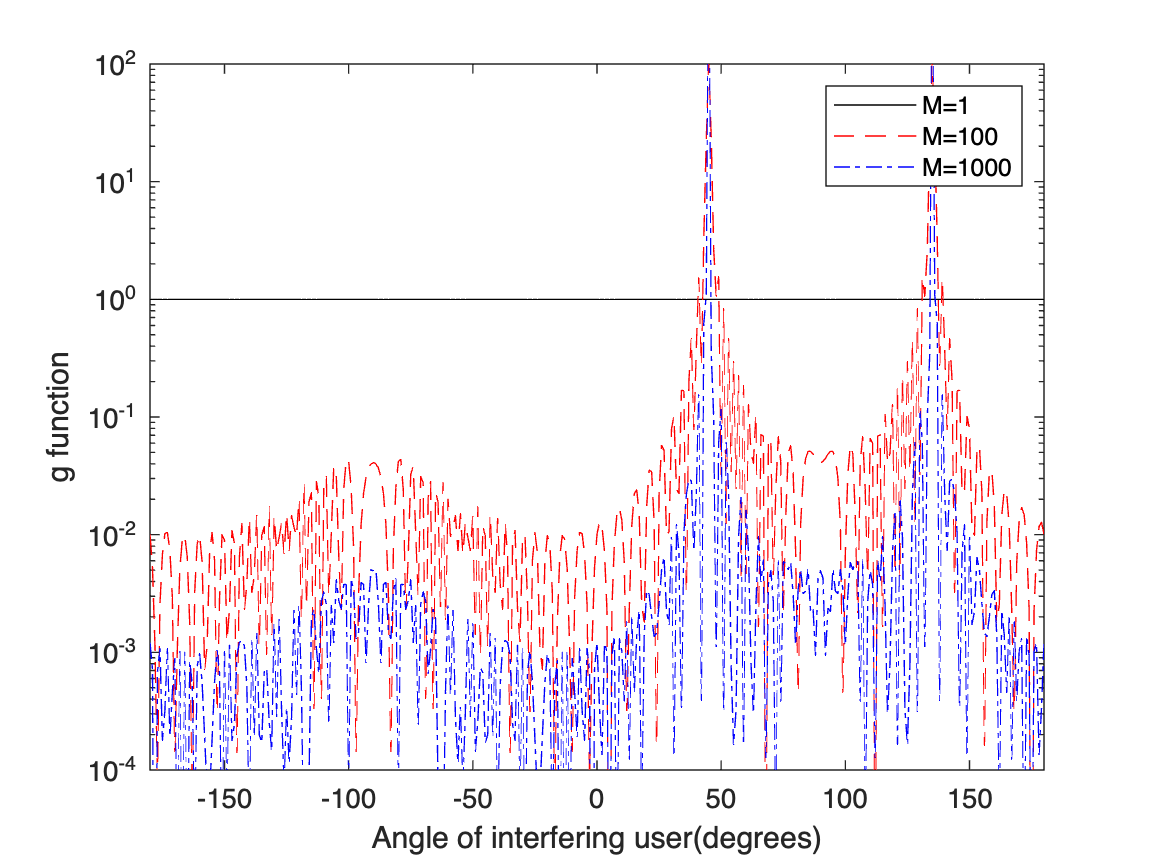

%plotting the curves obtained.
figure;
hold on; box on;

%M = 1
plot(Si1,G(1,:),"k-");

%M = 100
plot(Si1,G(2,:),"r--");

%M = 1000
plot(Si1,G(3,:),"b-.");

xlabel('Angle of interfering user(degrees)');
ylabel('g function');

%setting the log scale on y-axis to zoom in a lot.
set(gca,'Yscale','log');
xlim([-180 180]);
ylim([1e-4 1e2]);

%adding legends.
legend('M=1', 'M=100', 'M=1000')